clear, clc
datadir = 'G:\A_arousal_analysis\data';
load(fullfile(datadir, 'A_arousal_connectivity_patterns.mat'))
load(fullfile(datadir, 'fig_cols.mat'))
cols = cols./255;
% fmriprepoutput = '/media/dell/Feng/ds003768_fmriprep';
fmriprepoutput = 'H:\ds003768_fmriprep';


subdirs = dir(fullfile(fmriprepoutput,'sub*'));
issub = [subdirs(:).isdir];
subIDs = {subdirs(issub).name}';
subIDs(ismember(subIDs,{'.','..'})) = [];
nsub = length(subIDs);

wake_PE = [];
sleep_PE = [];
for subj=1:nsub
    subID = subIDs{subj,1};
    subfuncdir = fullfile(fmriprepoutput, subID, 'func');
    load(fullfile(subfuncdir,[subID, '_n472.mat']))
    PE = [ones(4,1),  atanh(subFC(:, parcel_idx))]*b_pls;
    wake_PE = [wake_PE; mean(PE(1:2,:))];
    sleep_PE = [sleep_PE; mean(PE(3:4, :))];
end

roc = roc_plot([wake_PE(:,1); sleep_PE(:,1)], [ones(28, 1); zeros(28, 1)], 'color', 'k', 'noplot', 'twochoice', 'nooutput');
fprintf('\n PAES does NOT predict wakefulness vs sleep: ACC = %.04g%% ± %.04g%%, P = %.02g, AUC = %.02g, d = %.02g \n', roc.accuracy*100, roc.accuracy_se*100, roc.accuracy_p, roc.AUC, roc.Gaussian_model.d_a)


 PAES does NOT predict wakefulness vs sleep: ACC = 46.43% ± 9.425%, P = 0.85, AUC = 0.37, d = -0.38 



roc = roc_plot([wake_PE(:,2); sleep_PE(:,2)], [ones(28, 1); zeros(28, 1)], 'color', 'k', 'noplot', 'twochoice', 'nooutput');
close all
fprintf('\n NAES does NOT predict wakefulness vs sleep: ACC = %.04g%% ± %.04g%%, P = %.02g, AUC = %.02g, d = %.02g \n', roc.accuracy*100, roc.accuracy_se*100, roc.accuracy_p, roc.AUC, roc.Gaussian_model.d_a)


 NAES does NOT predict wakefulness vs sleep: ACC = 53.57% ± 9.425%, P = 0.85, AUC = 0.51, d = -0.041 


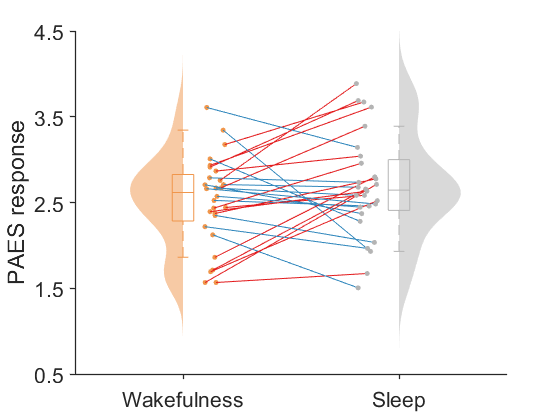



dataConditions = {wake_PE(:,1), sleep_PE(:,1)};
conditionLabels = {'Wakefulness', 'Sleep'};

lefthigher = dataConditions{1} > dataConditions{2};
linecolors{1} = zeros(length(lefthigher), 3);
linecolors{1}(lefthigher, :) = repmat([0.1961    0.5333    0.7412], sum(lefthigher), 1);
linecolors{1}(~lefthigher, :) = repmat([0.8902    0.1020    0.1098], sum(~lefthigher), 1);


plotPairedComparison(dataConditions, conditionLabels, 'dotsize', 10, 'densityscalefactor', 0.12, 'connectwidth', 0.5, 'colors', cols(1:3,:), 'linecolors',linecolors);
%plotPairedComparison(dataConditions, conditionLabels, 'dotsize', 10, 'densityscalefactor', 0.1, 'connectwidth', 0.5, 'colors', cols(1:3,:));

ylabel('PAES response');
set(gca,'YLim', [0.5 4.5], 'ytick',0.5:4.5, 'tickdir', 'out');
set(gca,'FontName','Helvetica','FontSize',16, 'LineWidth', 1)

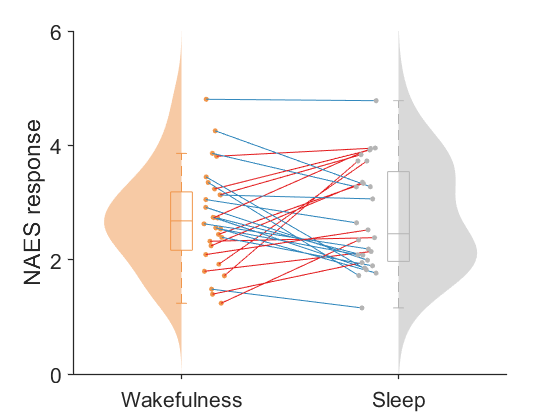


% % axis square
% set(gcf, 'Color', 'w');
% set(gcf, 'PaperUnits', 'inches');
% set(gcf, 'PaperPosition', [0 0 6.5 5.5]);
% print('-dtiff', 'A_PAES_study4.tif', '-r400')
% close all

dataConditions = {wake_PE(:,2), sleep_PE(:,2)};
conditionLabels = {'Wakefulness', 'Sleep'};

lefthigher = dataConditions{1} > dataConditions{2};
linecolors{1} = zeros(length(lefthigher), 3);
linecolors{1}(lefthigher, :) = repmat([0.1961    0.5333    0.7412], sum(lefthigher), 1);
linecolors{1}(~lefthigher, :) = repmat([0.8902    0.1020    0.1098], sum(~lefthigher), 1);


plotPairedComparison(dataConditions, conditionLabels, 'dotsize', 10, 'densityscalefactor', 0.1, 'connectwidth', 0.5, 'colors', cols(1:3,:), 'linecolors',linecolors);
%plotPairedComparison(dataConditions, conditionLabels, 'dotsize', 10, 'densityscalefactor', 0.1, 'connectwidth', 0.5, 'colors', cols(1:3,:));

ylabel('NAES response');
set(gca,'YLim', [0 6], 'ytick',0:2:6, 'tickdir', 'out');
set(gca,'FontName','Helvetica','FontSize',16, 'LineWidth', 1)


% % axis square
% set(gcf, 'Color', 'w');
% set(gcf, 'PaperUnits', 'inches');
% set(gcf, 'PaperPosition', [0 0 6.5 5.5]);
% print('-dtiff', 'A_NAES_study4.tif', '-r400')
% close all